
close all
clc
clear
%% Generation of noisy signal
% Enter your ID 
ID = 212466783;
 [inputSignal,fs,SNR_in] = inputSignalBuilder(ID);

SNR_in = -5.8095

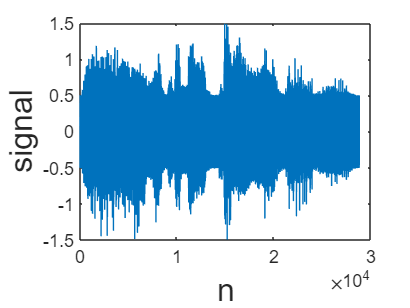

%soundsc(inputSignal,fs)
figure();plot(0:length(inputSignal)-1,inputSignal);
xlabel('n','fontsize',16);
ylabel('signal','fontsize',16);


audiowrite(['Input_' num2str(ID) '.wav'],inputSignal,fs)

[x, fs]= audioread('about_time.wav');
SNR_in = 10*log10(mean(x.^2)/mean((inputSignal-x).^2))

SNR_in = -5.8095


%% Noise frequency detection
%   In this part the input signal is examined. We assume a pure tone
%   disturbance of cos(w_0*n), and have to locate w_0=(2*pi/N)*k0
%   the cosine wave is periodic with N=512
%% Fourier Discrete Transform - Detect w_0 from the last frame of the signal
Nframe=512;
x_last_frame=inputSignal((end-Nframe+1):end);
e=length(inputSignal);
[X, omega]=my_DTFT((x_last_frame)',((e-Nframe+1):e),Nframe)

X = 1.0e+02 *

  -0.0003 + 0.0000i   0.0003 + 0.0002i  -0.0009 - 0.0001i   0.0007 - 0.0004i  -0.0005 - 0.0007i  -0.0007 + 0.0007i   0.0002 + 0.0004i   0.0009 - 0.0004i  -0.0000 - 0.0004i   0.0003 - 0.0000i  -0.0004 + 0.0012i   0.0006 - 0.0002i  -0.0000 + 0.0001i   0.0007 - 0.0003i  -0.0002 + 0.0002i  -0.0004 - 0.0000i   0.0001 - 0.0000i  -0.0003 + 0.0003i   0.0001 - 0.0004i  -0.0009 - 0.0003i  -0.0001 + 0.0008i   0.0006 - 0.0006i   0.0000 - 0.0006i  -0.0002 - 0.0002i   0.0003 + 0.0004i  -0.0003 + 0.0000i   0.0003 + 0.0004i  -0.0002 - 0.0003i   0.0001 + 0.0003i   0.0002 - 0.0003i  -0.0004 + 0.0003i   0.0001 + 0.0007i   0.0003 - 0.0000i  -0.0006 - 0.0002i   0.0006 + 0.0001i  -0.0002 - 0.0008i   0.0002 + 0.0000i   0.0001 + 0.0000i  -0.0002 + 0.0002i   0.0002 + 0.0003i   0.0005 - 0.0002i  -0.0001 + 0.0002i  -0.0009 - 0.0003i  -0.0003 - 0.0003i   0.0003 + 0.0007i   0.0002 + 0.0000i  -0.0005 - 0.0001i   0.0005 - 0.0005i  -0.0006 - 0.0005i  -0.0005 + 0.0002i


omega =    -3.1416   -3.1293   -3.1170   -3.1048   -3.0925   -3.0802   -3.0680   -3.0557   -3.0434   -3.0311   -3.0189   -3.0066   -2.9943   -2.9821   -2.9698   -2.9575   -2.9452   -2.9330   -2.9207   -2.9084   -2.8962   -2.8839   -2.8716   -2.8593   -2.8471   -2.8348   -2.8225   -2.8103   -2.7980   -2.7857   -2.7734   -2.7612   -2.7489   -2.7366   -2.7243   -2.7121   -2.6998   -2.6875   -2.6753   -2.6630   -2.6507   -2.6384   -2.6262   -2.6139   -2.6016   -2.5894   -2.5771   -2.5648   -2.5525   -2.5403


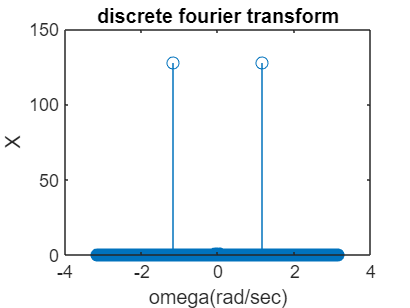

% plot x_last_frame DTFT to detect w_0
% dont forget to define w axis to plot the DTFT in right scale
stem(omega, abs(X))
title('discrete fourier transform')
xlabel('omega(rad/sec)')
ylabel('X')



%% Band stop with III implementations
%%%%% Implemetation I : perfect filtering (FIR)
N = 1000;
n = -N:N;
B = pi/50;

w_0 = 1.16583;
h_1 = 2*cos(w_0.*n).*sin(B.*n)./(pi.*n);
h_1(N+1)= 2*B/pi;
% Note- you can use conv() function to filter the signal. 
% use the option 'same' to get the same output length.
% for example if you have: input-x filter-h:
% y= conv(x,h,'same') 
v1 =conv(inputSignal,h_1, 'same');
y_1=inputSignal-v1;
%soundsc(y_1,fs)

audiowrite(['Output_I_' num2str(ID) '.wav'],y_1,fs)

SNR_out = 10*log10(mean(x.^2)/mean((y_1-x).^2))

SNR_out = 21.9424

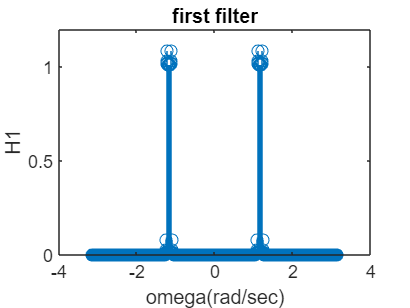

%%% Freaquency response- H_1(e^jw)
[H1,omega]=my_DTFT((h_1),n,N);
stem(omega,abs(H1))
title('first filter')
xlabel('omega(rad/sec)')
ylabel('H1')



%TODO
%%
%%%%% Implemetation II : ZOH design (FIR)
N = 100;
n = -N:N;
w_0 = 1.16583;
h_2 = (2*cos(w_0.*n))/(2*N+1);
v2=conv(inputSignal,h_2, 'same');
y_2 = inputSignal-v2;
soundsc(y_2,fs)

audiowrite(['Output_II_' num2str(ID) '.wav'],y_2,fs)

SNR_out = 10*log10(mean(x.^2)/mean((y_2-x).^2))

SNR_out = 24.2842

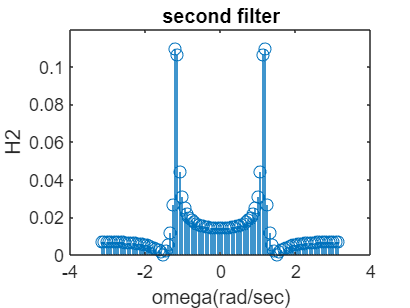


%%% Freaquency response- H_2(e^jw)
[H2, omega]=my_DTFT((h_2),n,N);
stem(omega,abs(H2))
title('second filter')
xlabel('omega(rad/sec)')
ylabel('H2')



%TODO

%%
%%%%% Implemetation III : recursive design (IIR)
w_0 =1.16583;
alpha = 0.999;
z_1(1)=0;z_2(1)=0; % initial rest
for n=2:length(inputSignal)
   z_1(n) =alpha*exp(1i*w_0)*z_1(n-1)+(1-alpha)*inputSignal(n) ;
   z_2(n) =alpha*exp(-1i*w_0)*z_2(n-1)+(1-alpha)*inputSignal(n) ;
   y_3(n,1) =inputSignal(n)- z_1(n)-z_2(n);
end

audiowrite(['Output_III_' num2str(ID) '.wav'],y_3,fs)

SNR_out = 10*log10(mean(x.^2)/mean((y_3-x).^2))

SNR_out = 11.7946

X3 = 1.0e+03 *

  -0.0059 - 0.0000i   0.0049 - 0.0033i  -0.0037 + 0.0045i   0.0005 - 0.0047i   0.0016 + 0.0045i  -0.0038 - 0.0032i   0.0063 + 0.0016i  -0.0052 + 0.0005i   0.0029 - 0.0044i  -0.0015 + 0.0054i  -0.0007 - 0.0047i   0.0030 + 0.0030i  -0.0040 - 0.0020i   0.0046 - 0.0012i  -0.0049 + 0.0015i   0.0034 - 0.0037i  -0.0002 + 0.0044i  -0.0023 - 0.0024i   0.0027 + 0.0042i  -0.0043 - 0.0012i   0.0024 - 0.0001i  -0.0037 + 0.0026i  -0.0004 - 0.0038i  -0.0009 + 0.0029i  -0.0028 - 0.0040i   0.0027 + 0.0004i  -0.0048 - 0.0002i   0.0032 - 0.0017i  -0.0021 + 0.0023i   0.0009 - 0.0040i   0.0022 + 0.0021i  -0.0015 - 0.0015i   0.0033 + 0.0017i  -0.0018 + 0.0007i   0.0029 - 0.0013i  -0.0012 + 0.0032i  -0.0009 - 0.0024i   0.0002 + 0.0043i  -0.0034 - 0.0004i   0.0025 - 0.0000i  -0.0025 + 0.0012i   0.0012 - 0.0024i  -0.0018 + 0.0030i  -0.0009 - 0.0034i   0.0020 + 0.0014i  -0.0021 - 0.0001i   0.0022 - 0.0009i  -0.0016 + 0.0008i  -0.0004 - 0.0019i   0.0003 + 0.0011i


H3 =    0.9937 + 0.0000i   1.0344 - 0.0084i   0.9500 - 0.0334i   0.9867 + 0.0715i   1.0400 - 0.0176i   0.9942 + 0.0041i   1.0148 - 0.0289i   0.9337 + 0.0123i   1.0179 + 0.0623i   1.0191 - 0.0324i   0.9982 + 0.0064i   0.9971 - 0.0509i   0.9426 + 0.0532i   1.0608 + 0.0377i   0.9807 - 0.0378i   1.0033 + 0.0043i   0.9607 - 0.0313i   0.9527 + 0.0935i   1.0512 - 0.0457i   0.9586 - 0.0253i   1.0116 - 0.0003i   0.9525 + 0.0107i   1.0149 + 0.0891i   0.9965 - 0.1131i   0.9560 + 0.0058i   1.0100 - 0.0024i   0.9697 + 0.0347i   1.0929 + 0.0172i   0.9512 - 0.0983i   0.9699 + 0.0435i   1.0058 - 0.0077i   1.0045 + 0.1020i   1.0663 - 0.0647i   0.8547 - 0.1085i   1.0209 + 0.0635i   0.9950 - 0.0081i   1.0369 + 0.0755i   0.9797 - 0.0775i   0.8996 - 0.0159i   1.0571 + 0.0640i   0.9885 - 0.0036i   1.0762 + 0.0219i   0.9254 - 0.0660i   0.9484 + 0.0850i   1.0833 + 0.0189i   0.9845 + 0.0021i   1.0803 - 0.0407i   0.8083 - 0.0369i   0.9167 + 0.1579i   1.1656 - 0.0818i


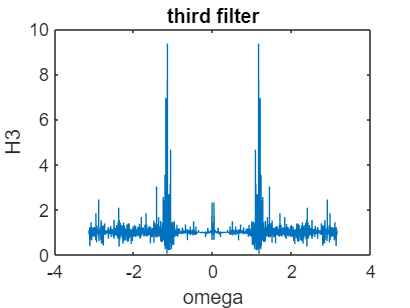

%soundsc(y_3,fs)

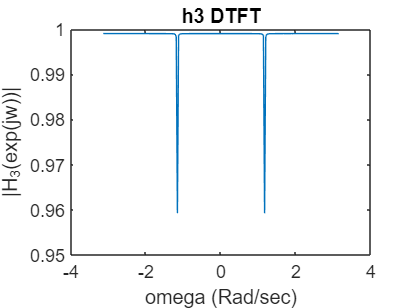



z_1=0;z_2=0; % initial rest
delta_input=zeros(length(inputSignal),1);
delta_input(1)=1;
for n=1:length(inputSignal)
   z_1 =alpha*exp(1i*w_0)*z_1+(1-alpha)*delta_input(n) ;
   z_2 =alpha*exp(-1i*w_0)*z_2+(1-alpha)*delta_input(n) ;
   h_3(n,1) = delta_input(n)- z_1 -z_2;
end

N=200;
l=(1:length(inputSignal));
h_3=h_3';
[X, omega]= my_DTFT(h_3,l,N);
plot(omega,abs(X));
title('h3 DTFT')
  xlabel('omega (Rad/sec)')
  ylabel('|H_3(exp(jw))|')


%%DTFT of 
%% Performace evaluation:

[Grade, SNR_out_ref]= GradeMyOutput(ID,y_1,1);

SNR_in = -5.8095

SNR_out_ref = 17.2341

SNR_out = 21.9424

performance = 100

[Grade, SNR_out_ref]= GradeMyOutput(ID,y_2,2);

SNR_in = -5.8095

SNR_out_ref = 24.2842

SNR_out = 24.2842

performance = 100

[Grade, SNR_out_ref]= GradeMyOutput(ID,y_3,3);

SNR_in = -5.8095

SNR_out_ref = 11.7979

SNR_out = 11.7946

performance = 100